%This file implements the kalman filter for the project 2
%for the radar sensing range detection for the position
%of the object in 2D space

%gets sigma_n squared, the variance of n
var_n = sigma_n^2

var_n = 100


%gets sigma_u squared, the variance of u
var_u = sigma_u^2

var_u = 1.0000e-04


%creates the A matrix
A = [1 0 T 0 (T^2)/2 0; 0 1 0 T 0 (T^2)/2; 0 0 1 0 T 0; 0 0 0 1 0 T; 0 0 0 0 1 0; 0 0 0 0 0 1];


%creates the B matrix
B = [0 0; 0 0; 0 0; 0 0; 1 0; 0 1];

%creates the C matrix
C = [1 0 0 0 0 0; 0 1 0 0 0 0];

%begins project by plotting the actual s vs y_pq

%creates indexing matrix
n = linspace(1,N,N)

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



%gets the p portion of s
s_p = s(1,:)

s_p = 1.0e+03 *

         0    0.0001    0.0002    0.0003    0.0005    0.0006    0.0008    0.0009    0.0011    0.0013    0.0014    0.0015    0.0017    0.0019    0.0021    0.0023    0.0024    0.0026    0.0028    0.0030    0.0032    0.0035    0.0037    0.0040    0.0042    0.0045    0.0049    0.0053    0.0057    0.0061    0.0067    0.0072    0.0078    0.0085    0.0093    0.0101    0.0110    0.0119    0.0129    0.0140    0.0151    0.0163    0.0175    0.0188    0.0201    0.0215    0.0230    0.0245    0.0261    0.0277


s_q = s(2,:)

s_q =          0   -0.1000   -0.2048   -0.3176   -0.4331   -0.5468   -0.6501   -0.7391   -0.8150   -0.8730   -0.9134   -0.9428   -0.9666   -0.9847   -1.0095   -1.0559   -1.1310   -1.2432   -1.3948   -1.5798   -1.8009   -2.0656   -2.3723   -2.7176   -3.1060   -3.5424   -4.0223   -4.5328   -5.0732   -5.6526   -6.2799   -6.9681   -7.7185   -8.5236   -9.3861  -10.3075  -11.2806  -12.3072  -13.3873  -14.5191  -15.7025  -16.9349  -18.2118  -19.5231  -20.8700  -22.2597  -23.6954  -25.1794  -26.7084  -28.2802


%gets the y_pq
y_p = y_pq(1,:)

y_p = 1.0e+03 *

   -0.0066   -0.0208   -0.0123   -0.0072    0.0097    0.0060    0.0042   -0.0230    0.0055    0.0277   -0.0044    0.0064   -0.0139    0.0010   -0.0136    0.0186    0.0020    0.0185   -0.0108    0.0179    0.0060    0.0006   -0.0014    0.0210   -0.0007    0.0134    0.0079    0.0016    0.0143    0.0016   -0.0030   -0.0091    0.0139    0.0171    0.0184    0.0203    0.0083    0.0187    0.0160    0.0219    0.0177    0.0372    0.0258    0.0033    0.0294    0.0179    0.0262    0.0409    0.0299    0.0357


y_q = y_pq(2,:)

y_q =    -3.3248    4.7359    1.4175   -5.2808   -9.7437   -1.9525  -11.5317   -5.3835   -0.9510   -6.6860    0.0294   -0.6103    8.2412   -5.9456   -0.4647   14.3033   -1.7212  -13.3396    1.4483    9.3644   -4.9417  -14.8412    1.1202    1.2020   -1.2501   -8.6484   -3.8535  -14.9279  -10.5208   -8.2060   -0.8567   -7.0409   -6.4705   -4.7910  -10.9615   -8.1597   -6.9188  -14.4356  -26.5256  -24.0438   -0.4105  -12.7271  -18.2318  -12.5892  -28.3884  -28.7559  -31.8695  -10.3377  -28.6727  -36.9384


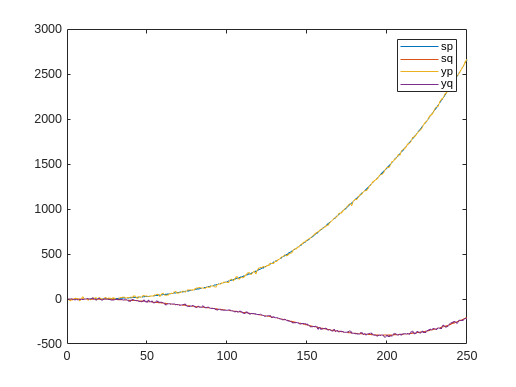


plot(n, s_p, n, s_q, n, y_p, n, y_q)
%legend for the plot
legend('sp', 'sq', 'yp', 'yq')

title("Input data comparison. Actual vs measured sp and sq.")



%Creates the 




